# TPA 3 MPC Grupo 10

A contiunación se obtiene el modelo discrete en espacio de estados a partir del modelo de orden 6 obtenido en el TP1 (identificación)

close all; clc;
s = tf('s');

% addpath(genpath('...'));
% savepath

% modelo de orden 6
model_6 = 1/(( (10e3)*(10e-6)*s + 1 )^6)


model_6 =
 
                                   1
  --------------------------------------------------------------------
  1e-06 s^6 + 6e-05 s^5 + 0.0015 s^4 + 0.02 s^3 + 0.15 s^2 + 0.6 s + 1
 
Continuous-time transfer function.
Model Properties



[p, z] = pzmap(model_6);
high_freq_pole = abs(max(p));

% TIEMPO DE MUESTREO
Ts = round(1/(5*high_freq_pole), 3)

Ts = 0.0200


model_discrete = c2d(model_6, Ts)


model_discrete =
 
  7.491e-08 z^5 + 3.6e-06 z^4 + 1.608e-05 z^3 + 1.354e-05 z^2 + 2.152e-06 z + 3.179e-08
  -------------------------------------------------------------------------------------
          z^6 - 4.912 z^5 + 10.05 z^4 - 10.98 z^3 + 6.74 z^2 - 2.207 z + 0.3012
 
Sample time: 0.02 seconds
Discrete-time transfer function.
Model

[model_A, model_B, model_C, model_D] = tf2ss(model_discrete.Numerator{1}, model_discrete.Denominator{1});

Se verifican los modelos continuos y discretos comparando sus respuestas al escalón

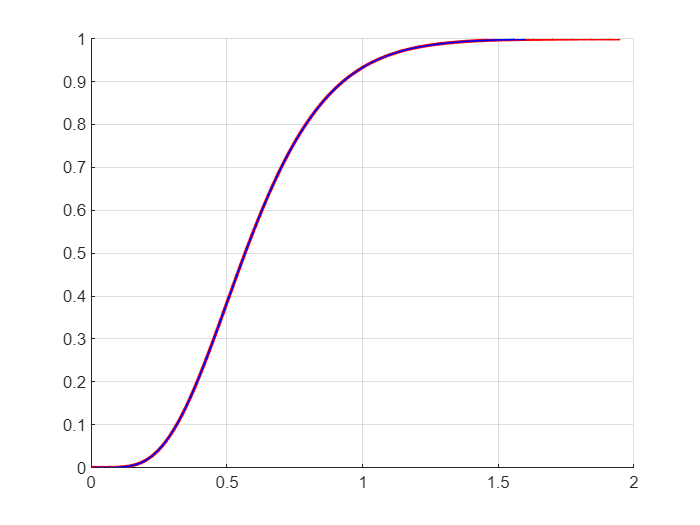

[cont_y, cont_t] = step(model_6);
[disc_y, disc_t] = step(model_discrete);

figure; hold on; grid on;
plot(cont_t, cont_y, 'r', 'LineWidth', 2);
plot(disc_t, disc_y, 'b', 'LineWidth', 1);

Ahora se obtiene el modelo en espacio de estados pero considerando variaciones en la entrada en de las muestras $\Delta U$(modelo incremental = inc_model)

% A_expanded = [model_A, model_B; zeros(1, length(model_A)), ones(1, 1)];
A_expanded = [model_A, zeros(length(model_A),1); model_C*model_A, ones(1, 1)];
% B_expanded = [model_B; ones(1, 1)];
B_expanded = [model_B; model_C*model_B];
C_expanded = [zeros(1,length(model_A)), 1];

inc_model = ss(A_expanded, B_expanded, C_expanded, 0, Ts)


inc_model =
 
  A = 
               x1          x2          x3          x4          x5          x6          x7
   x1       4.912      -10.05       10.98       -6.74       2.207     -0.3012           0
   x2           1           0           0           0           0           0           0
   x3           0           1           0           0           0           0           0
   x4           0           0           1           0           0           0           0
   x5           0           0           0           1           0           0           0
   x6           0           0           0           0           1           0           0
   x7   3.968e-06   1.532e-05   1.436e-05   1.647e-06   1.971e-07  -2.256e-08           1
 
  B = 
              u1
   x1          1
   x2          0
   x3          0
   x4          0
   x5          0
   x6          0
   x7  7.491e-08
 
  C = 
       x1  x2  x3  x4  x5  x6  x7
   y1   0   0   0   0   0   0   1
 
  D = 
       u1
   y1   0
 
Sampl


ref=zeros(1, 5/Ts); ref(1)=1;
[y, t] = lsim(inc_model, ref)

y =          0
    0.0000
    0.0000
    0.0000
    0.0002
    0.0006
    0.0015
    0.0032
    0.0060
    0.0104


t =          0
    0.0200
    0.0400
    0.0600
    0.0800
    0.1000
    0.1200
    0.1400
    0.1600
    0.1800


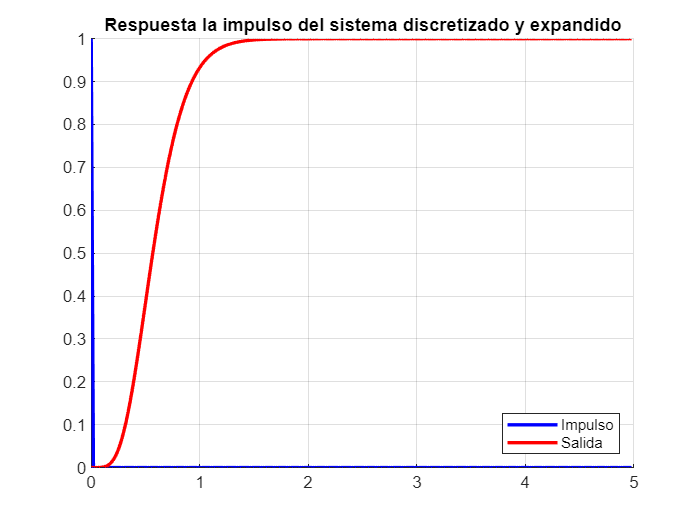

figure(); grid on; hold on;
plot(t, ref, 'b', 'LineWidth', 2);
plot(t, y, 'r', 'LineWidth', 2);
legend('Impulso', 'Salida', 'Location', 'southeast');
title('Respuesta la impulso del sistema discretizado y expandido')

Se cargan las matrices F y $\phi \;$

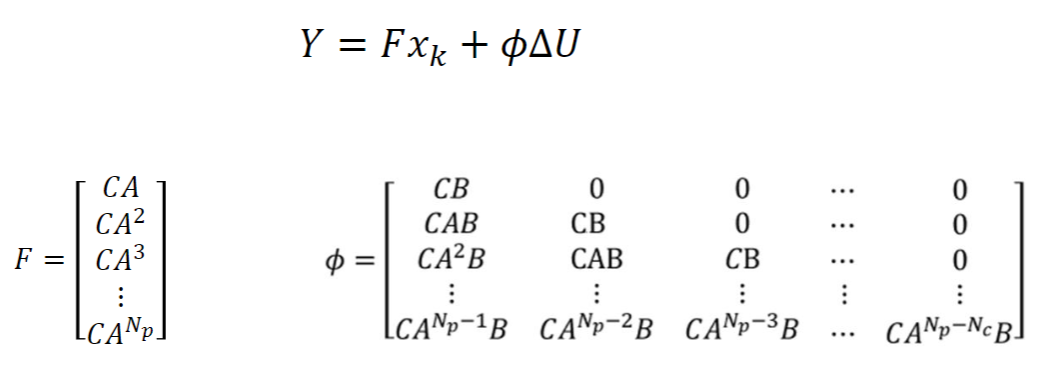

## Para calcular Np consideré que si Ts=0.02 y Tr=1.4 entonces entran aproximadamente 70 muestras hasta que se extinguen los transitorios

Np = round(1.4/Ts);
Nc = 3;

% Esto genera F para un rango dinámico Np
F_mat = zeros(Np, length(A_expanded));
F_mat(1, :) = C_expanded*A_expanded;
for i = 2:Np
    F_mat(i, :) = F_mat(i-1, :)*A_expanded;
end
F_mat

F_mat =     0.0000    0.0000    0.0000    0.0000    0.0000   -0.0000    1.0000
    0.0000   -0.0000    0.0001   -0.0000    0.0000   -0.0000    1.0000
    0.0002   -0.0003    0.0004   -0.0003    0.0001   -0.0000    1.0000
    0.0006   -0.0014    0.0018   -0.0012    0.0004   -0.0001    1.0000
    0.0015   -0.0042    0.0054   -0.0036    0.0013   -0.0002    1.0000
    0.0032   -0.0097    0.0129   -0.0089    0.0031   -0.0005    1.0000
    0.0060   -0.0193    0.0263   -0.0184    0.0066   -0.0010    1.0000
    0.0104   -0.0344    0.0479   -0.0341    0.0124   -0.0018    1.0000
    0.0166   -0.0565    0.0798   -0.0576    0.0211   -0.0031    1.0000
    0.0249   -0.0867    0.1242   -0.0905    0.0334   -0.0050    1.0000



% Esto genera phi para un rango dinámico de Np y Nc
phi_mat = zeros(Np, Nc);
% phi_mat = cell(Np, Nc);
for j = 1:Nc
    for i = 1:Np
        if (i < j)
            phi_mat(i, j) = 0;
            % phi_mat{i,j}='0';
        elseif (i == j)
            phi_mat(i, j) = C_expanded*B_expanded;
            % phi_mat{i,j}=sprintf('CB');
        else
            phi_mat(i, j) = C_expanded*(A_expanded^(i-j))*B_expanded;
            % phi_mat{i,j}=sprintf('CA^(%d)B', i-j);
        end
    end
end
phi_mat

phi_mat =     0.0000         0         0
    0.0000    0.0000         0
    0.0000    0.0000    0.0000
    0.0002    0.0000    0.0000
    0.0006    0.0002    0.0000
    0.0015    0.0006    0.0002
    0.0032    0.0015    0.0006
    0.0060    0.0032    0.0015
    0.0104    0.0060    0.0032
    0.0166    0.0104    0.0060


A continuación se calculan las entradas $\Delta U$de manera analítica

states = zeros(length(A_expanded), 1);
ref_weight_mat = 0.1*eye(Nc);
Rs = ones(Np, 1);
reference=1;
% A=(((phi_mat')*phi_mat+ref_weight_mat)^(-1))*(phi_mat')
% B=(Rs*reference-F_mat*states)
% A*B
phi_transposed=transpose(phi_mat);
dU = (((phi_transposed*phi_mat+ref_weight_mat)^(-1))*(phi_transposed))*(Rs*reference-F_mat*states)

dU =     3.3889
    0.2807
   -2.5547



% Rs*reference
% F_mat*states
% (Rs*reference-F_mat*states)

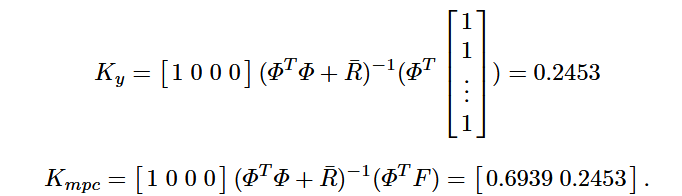

Np = round(1.4/Ts)

Np = 70

Nc = 3;
reference = 1;
rw = 0.8;
ref_weight_mat = rw*eye(Nc);

Phi_Phi=phi_transposed*phi_mat;

% Estas son las matrices que voy a cargar al uC
% No estoy seguro de si se calculan así
firstOneAndZeros = zeros(1, length(Phi_Phi));
firstOneAndZeros(1) = 1;

Phi_Phi_R_INV = ((Phi_Phi+ ref_weight_mat)^(-1));
Ky = firstOneAndZeros * (Phi_Phi_R_INV  * ((phi_transposed)*ones(length(phi_mat), 1)))

Ky = 0.8831

Kmpc = firstOneAndZeros * Phi_Phi_R_INV * (phi_transposed*F_mat)

Kmpc =     0.3864   -1.4863    2.2990   -1.7852    0.6954   -0.1087    0.8831


Guardo los valores en archivos .h para el codigo en C

scaling_factor = 1;

filename='codigo/include/weights.h';
fid = fopen(filename, 'w');
if fid == -1
    error('Error opening the file: %s', filename);
end

fprintf(fid, "#define SCALING_FACTOR %d\n\n", scaling_factor);
guard = upper(strrep('Ky.h', '.', '_'));
fprintf(fid, '#ifndef %s\n#define %s\n\n', guard, guard);
fprintf(fid, "const double Ky = %f;\n\n", (scaling_factor*Ky));
fprintf(fid, '#endif // %s\n\n', guard);

guard = upper(strrep('Kmpc.h', '.', '_'));
fprintf(fid, '#ifndef %s\n#define %s\n\n', guard, guard);
fprintf(fid, "const double Kmpc[%d] = {",  length(Kmpc));
for i=1:(length(Kmpc)-1)
    fprintf(fid, " %f,", (scaling_factor*Kmpc(i)));
end
fprintf(fid, " %f};\n\n", Kmpc(length(Kmpc)));
fprintf(fid, '#endif // %s\n', guard);

fclose(fid);

Ahora se hace una simulación de la acción de control en diferencias (la acción de control se pasa de 5V, no es realizable)

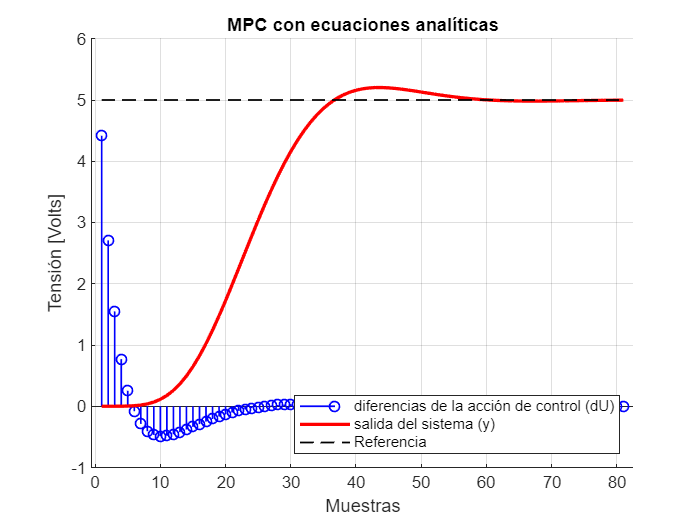

sim_length = 81;
x = zeros(1, sim_length);
y = zeros(1, sim_length);
u = zeros(1, sim_length);
ac = zeros(1, sim_length);
lastU = 0;
states=zeros(length(A_expanded), 1);

reference = 5;

for i = 1:sim_length
    % dU = ((Phi_Phi + ref_weight_mat)^(-1)) * ( Phi_R - Phi_F *  states);
    dU = (((phi_transposed*phi_mat+ref_weight_mat)^(-1))*(phi_transposed))*(Rs*reference-F_mat*states);
    x(i) = dU(1);

    lastU = lastU + x(i);
    u(i) = lastU;
    ac(i) = lastU;
    states = A_expanded*(states) + B_expanded*x(i);
    y(i) = C_expanded*states;
end

fig = figure();
hold on; grid on;
ylabel('Tensión [Volts]');
xlabel('Muestras');

stem(x, 'b', 'LineWidth', 1);
plot(y, 'r', 'LineWidth', 2);
% stairs(y, 'm', 'LineWidth', 1);
plot(ones(1, length(y))*reference, '--k', 'LineWidth', 1);

title('MPC con ecuaciones analíticas');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia', 'Location', 'southeast');

Simulo los Ky y Kmpc que calculé, también limito la acción de control así se parece más a lo que voy a implementar en el $\mu C$

sim_length = 80;
x = zeros(1, sim_length);
y = zeros(1, sim_length);
u = zeros(1, sim_length);
lastU = 0;
states = zeros(length(A_expanded), 1);
states(7) = 0;

% states(1) = 1690/1000;
% states(2) = 484/1000;
% states(3) = 98/1000;
% states(4) = 20/1000;
% states(5) = 5/1000;
% states(6) = 5/1000;
% states(7) = 3817/1000*0;

% fprintf("acc: %f\n",Kmpc*states);

reference = 5000;
scaling_factor = 1;

for i = 1:sim_length
    acc = int32(0);
    for j = 1:length(states)
        acc = int32(acc) + int32(single(Kmpc(j))*single(states(j)));
    end
    dU = int32(int32(single(Ky)*single(reference)) - int32(acc));
    x(i) = int32(dU(1));
    lastU = int16(lastU + x(i));
    if (lastU > 5000)
        lastU = 5000;
    elseif (lastU < 0)
        lastU = 0;
    end
    u_percent = (lastU / 5000) * 100;
    u(i) = int16(lastU);
    fprintf("dU: %f\nU: %f\nacc: %f\nduty cycle: %d%%\nStates->(%d,%d,%d,%d,%d,%d,%d)\n\n", dU(1), lastU, acc, u_percent, states(1), states(2), states(3), states(4), states(5), states(6), states(7));
    states = (A_expanded*(states)) + (B_expanded*x(i));
    % states = min(states, 2^32);
    y(i) = C_expanded*states;
    states(1) = int32(states(1))  ;
    states(2) = int32(states(2) ) ;
    states(3) = int32(states(3) ) ;
    states(4) = int32(states(4) ) ;
    states(5) = int32(states(5) ) ;
    states(6) = int32(states(6) ) ;
    states(7) = int32(states(7 )) ;
end

dU: 4415.000000
U: 4415.000000
acc: 0.000000
duty cycle: 100%
States->(0,0,0,0,0,0,0)

dU: 2709.000000
U: 5000.000000
acc: 1706.000000
duty cycle: 100%
States->(4415,0,0,0,0,0,0)

dU: 1549.000000
U: 5000.000000
acc: 2866.000000
duty cycle: 100%
States->(24397,4415,0,0,0,0,0)

dU: 769.000000
U: 5000.000000
acc: 3646.000000
duty cycle: 100%
States->(77005,24397,4415,0,0,0,0)

dU: 253.000000
U: 5000.000000
acc: 4162.000000
duty cycle: 100%
States->(182200,77005,24397,4415,0,0,1)

dU: -81.000000
U: 4919.000000
acc: 4496.000000
duty cycle: 100%
States->(359050,182200,77005,24397,4415,0,3)

dU: -287.000000
U: 4632.000000
acc: 4702.000000
duty cycle: 100%
States->(622262,359050,182200,77005,24397,4415,8)

dU: -410.000000
U: 4222.000000
acc: 4825.000000
duty cycle: 100%
States->(979709,622262,359050,182200,77005,24397,19)

dU: -468.000000
U: 3754.000000
acc: 4883.000000
duty cycle: 100%
States->(1431200,979709,622262,359050,182200,77005,38)

dU: -486.000000
U: 3268.000000
acc: 4901.000000
duty

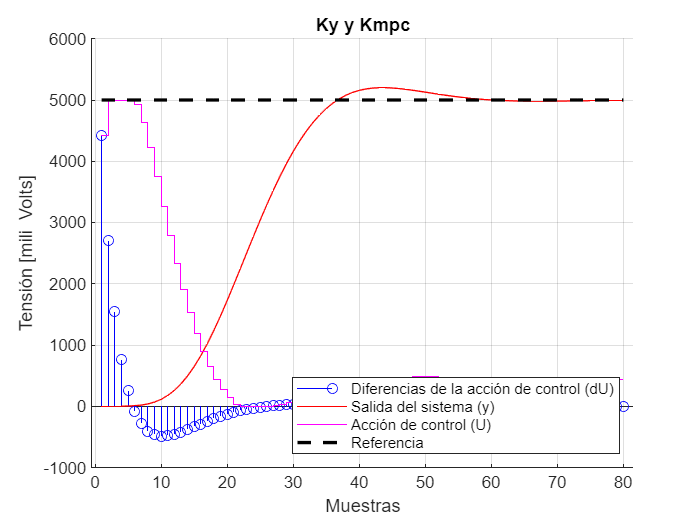


fig = figure();
hold on; grid on;
ylabel('Tensión [mili  Volts]');
xlabel('Muestras');

stem(x, 'b');
plot(y, 'r');
stairs(u, 'm');
plot(reference*(ones(1, length(y))), '--k', 'LineWidth', 2);

title('Ky y Kmpc');
legend('Diferencias de la acción de control (dU)', 'Salida del sistema (y)', 'Acción de control (U)', 'Referencia', 'Location', 'southeast');

Ahora si quiero aplicar restricciones a la acción de control por ejemplo, no podría resolverlo de manera analítica, necesitaria usar un solver, por ejemplo empleo uno de la librería yamilp:

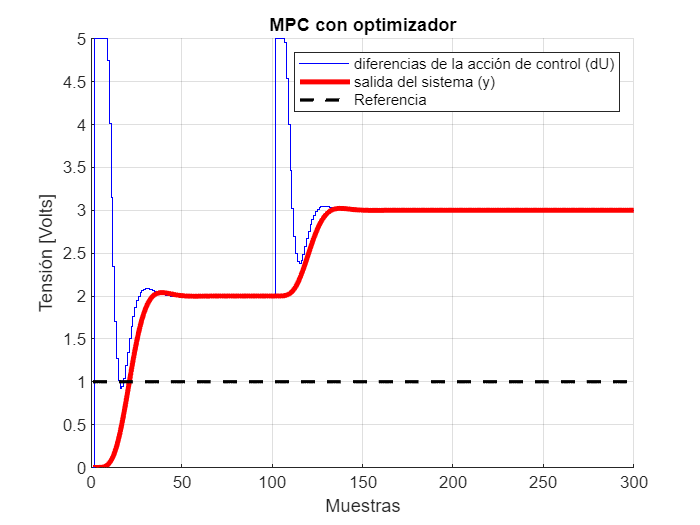

nx = length(A_expanded);                     
nu = 1;                      
ny = 1;                      

rw=.1;
R = rw * eye(nu);

% YALMIP
uant = sdpvar(1);
u = sdpvar(Nc, nu);
x = sdpvar(nx, Np+1);
r = sdpvar(1, ny);

constraints = [];
objective = 0;

for k = 1:Nc
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k) + B_expanded*u(k)];
    constraints = [constraints, 0 <= (sum(u(1:k)) + uant) <= 5];
    objective = objective + (r - C_expanded*x(:,k+1))' * (r - C_expanded*x(:,k+1)) + u(k)' * R * u(k);
end

% Condiciones y coste
for k = Nc+1:Np
    constraints = [constraints, x(:,k+1) == A_expanded*x(:,k)];
    objective = objective + (r - C_expanded*x(:,k+1))' * (r - C_expanded*x(:,k+1));
end

ops = sdpsettings();
controller = optimizer(constraints, objective, ops, {x(:,1), r, uant}, u(:));

% simulacion
state = zeros(nx, 1);             
r_sim = 2*ones(300, ny); r_sim(101:300, 1)=3;
sim_steps = length(r_sim);                
du = zeros(Nc, sim_steps); 
ys = zeros(sim_steps, 1);   
ac = zeros(sim_steps, 1);
ac(1) = 0;
for k = 1:sim_steps
    [u_opt, diagnostics] = controller({state, r_sim(k), ac(k)});
    
    if diagnostics == 1
        error('Error con el controller/solver');
    end
    
    u_k = u_opt(1);
    du(1, k) = u_k;
    
    ac(k+1) = ac(k) + u_k;
    y_k = C_expanded*state;    
    state = A_expanded*state + B_expanded*u_k;

    ys(k) = y_k;
end

figure; hold on; grid on;
% stem(du(1, :), 'm');
stairs(ac, 'b');
plot(ys, 'r', 'LineWidth', 3);
plot(ones(1, length(ys)), '--k', 'LineWidth', 2);
xlim([0 sim_steps])

title('MPC con optimizador');
ylabel('Tensión [Volts]');
xlabel('Muestras');
legend('diferencias de la acción de control (dU)', 'salida del sistema (y)', 'Referencia', 'Location', 'Northeast');